# Filter Design

`Filtering means removing unwanted components from a signal. There are mainly 4 types of filter:`

- `High-Pass Filter`

- `Low-Pass Filter`

- `Band-Pass Filter`

- `Band-Stop Filter`

`Depending on the filter architechture there are mainly 3 types of filter:`

- `Moving Average Filter`

- `Finite Impulse Response (FIR) Filter`

- `Infinite Impulse Response (IIR) Filter`

### `MOVING AVERAGE FILTER`

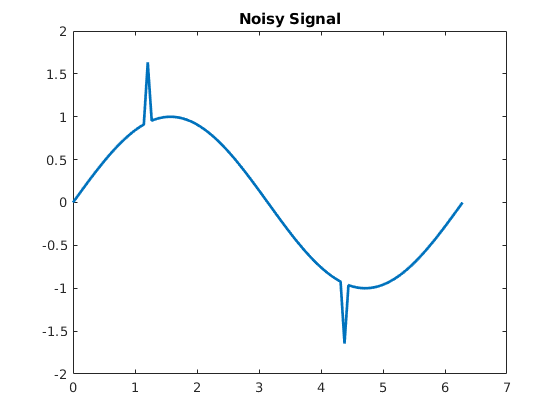

t = linspace(0, 2 * pi);
x = sin(t);
% ADDING NOISE
x(20) = x(20) + 0.7;
x(70) = x(70) - 0.7;
plot(t, x, 'LineWidth', 2);
title("Noisy Signal");

WL = 3

WL = 3

XF = zeros(1, length(x) - WL)

XF =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


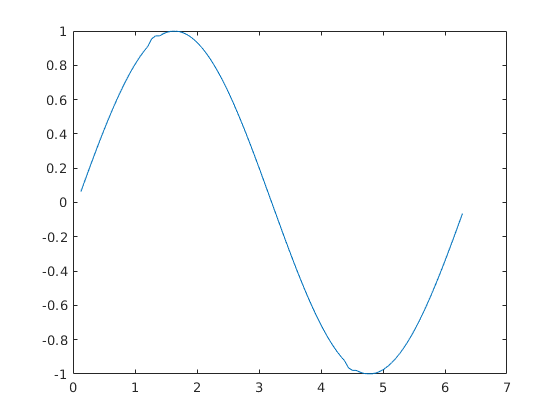


for i = WL : length(x) 
    % XF(i - WL + 1) = sum(x(i - WL + 1 : i)) / WL;
    XF(i - WL + 1) = median(x(i - WL + 1 : i));
end

plot(t(WL : end), XF);

### LOW PASS FILTER

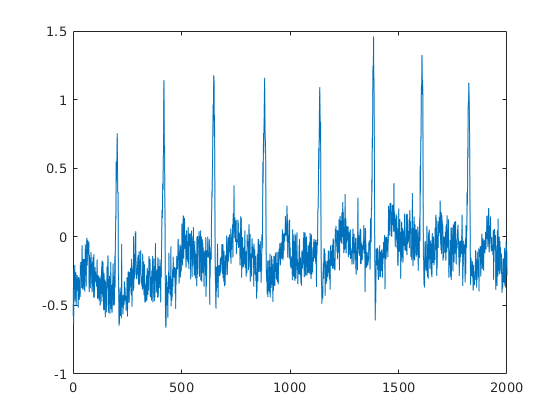

load ecg.mat
x = ecg + 0.1 * randn(size(ecg));
plot(x)
xlim([0, 2000])

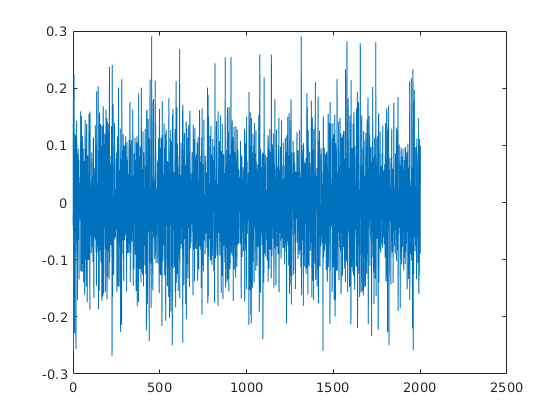


xf = filter(Hd, x);

plot(xf);

### HIGH PASS FILTER

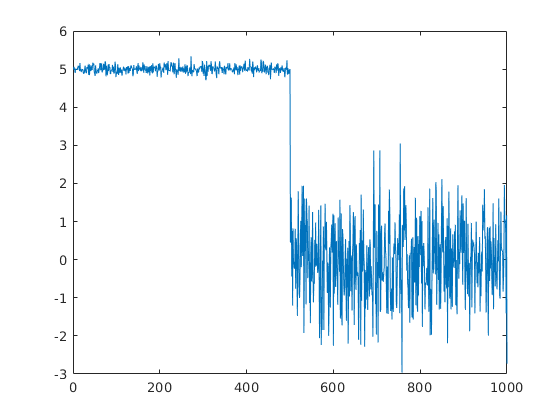

N = 1000;
x1 = 0.1 * randn(N/2, 1);
x2 = randn(N/2, 1);
x1 = x1 + 5;
plot([x1; x2])

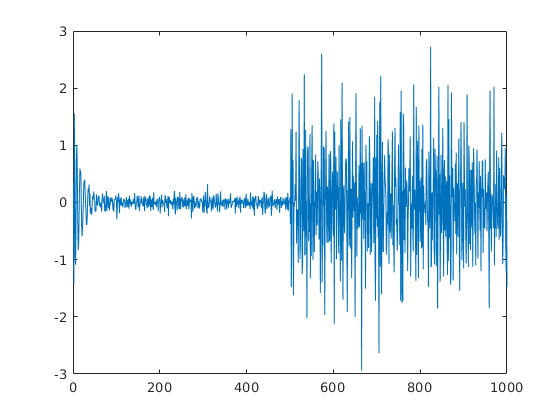

xf = filter(Hd, [x1; x2]);
plot(xf);